# CONTROLLO AVANZATO E APPLICAZIONI ___ 11/05/2026 ___ SALVATORE _ RAIOLA _ DE6000008

clear; close all; clc;


## 0) DEFINIZIONI 


A = [0,    1,   0,    0;
    -2, -0.6,   1,    0;
     0,    0,   0,    1;
     1,    0,-  3, -0.8];

B = [0,    0;
     1,  0.4;
     0,    0;
     0.3,  1];

C = [1, 0, 0, 0;
     0, 0, 1, 0
     0, 0, 0, 0;
     0, 0, 0, 0];

n = size(A,1);
m = size(B,2);
p = size(C,1);

D = zeros(2,m);

## 1) PROPRIETÀ STRUTTURALI DEL SISTEMA

### 1.1) Stabilità del sistema ciclo aperto


autovalori = eig(A)

autovalori =   -0.3713 + 1.8620i
  -0.3713 - 1.8620i
  -0.3287 + 1.1309i
  -0.3287 - 1.1309i



if all(real(autovalori) < 0)
    disp('Il sistema è asintoticamente stabile a ciclo aperto.');
elseif any(real(autovalori) > 0)
    disp('Il sistema è instabile.');
else
    disp('Il sistema è marginalmente stabile.');
end

Il sistema è asintoticamente stabile a ciclo aperto.


### 1.2) Controllabilità della coppia (A,B)


if(rank(ctrb(A,B))==n)
    disp('Il sistema è completamente controllabile');
else
    disp('Il sistema NON è completamente controllabile');
end

Il sistema è completamente controllabile


### 1.3) Osservabilità della coppia (A,C)


if(rank(obsv(A,C))==n)
    disp('Il sistema è completamente osservabile');
else
    disp('Il sistema NON è completamente osservabile');
end

Il sistema è completamente osservabile


## 2) ASSEGNAMENTO AUTOVALORI MEDIANTE METODO DI SYLVESTER

### 2.1) Specifiche

autovalori_desiderati = [-2; -2.5; -3; -3.5];
Lambda = diag(autovalori_desiderati);

### 2.2) Sintesi

% matrice G con elementi casuali
G = rand(2,4);

X = sylvester(A, -Lambda, -B*G);
K_EIG = G/X

K_EIG =    -1.5560   -4.1056   -2.8835    0.7718
    5.6116    3.3700   -9.5133   -7.0739


### 2.3) Verifica 

eig_cl = eig(A+B*K_EIG);

disp('Autovalori desiderati:'); disp(autovalori_desiderati);

Autovalori desiderati:
   -2.0000
   -2.5000
   -3.0000
   -3.5000



disp('Autovalori a ciclo chiuso:'); disp(eig_cl);

Autovalori a ciclo chiuso:
   -2.0000
   -3.5000
   -2.5000
   -3.0000



## 3) CONTROLLO LQR CON AZIONE INTEGRALE E Ts ASSEGNATO

### 3.1) Specifiche 

r = [1; -0.5];
x_0_lqr = [1;
           1;
           1;
           1];

Ts = 5;

### 3.2) Sistema Aumentato

C_LQR = [1, 0, 0, 0;
         0, 0, 1, 0];

p_a = size(C_LQR, 1);

A_a = [ A, zeros(n,p_a);
       -C_LQR, zeros(p_a,p_a)]

A_a =          0    1.0000         0         0         0         0
   -2.0000   -0.6000    1.0000         0         0         0
         0         0         0    1.0000         0         0
    1.0000         0   -3.0000   -0.8000         0         0
   -1.0000         0         0         0         0         0
         0         0   -1.0000         0         0         0


n_a = size(A_a,1);
B_a = [B;
       zeros(p_a,m)]

B_a =          0         0
    1.0000    0.4000
         0         0
    0.3000    1.0000
         0         0
         0         0


### 3.3) Sintesi

Q_x = eye(n);
Q_z = eye(p_a); 
Q_a = blkdiag(Q_x, Q_z);

R_a = eye(m);

% Trasliamo lo spettro di A
alpha = 4/Ts;

for iter = 1:500
    % Sintesi LQR sul sistema NOMINALE
    [K_LQR, ~, ~] = lqr(A_a, B_a, Q_a, R_a);
    
    % Calcolo del polo dominante
    poli_chiusi = eig(A_a - B_a*K_LQR);
    polo_dominante = max(real(poli_chiusi));
    
    % Se il polo dominante è troppo a destra (sistema lento)
    % dobbiamo aumentare il peso dello stato o diminuire quello del controllo
    if (polo_dominante > -alpha + 0.02)
        Q_a(n+1:end, n+1:end) = Q_a(n+1:end, n+1:end) * 1.1; 
    % Se è troppo a sinistra  (sistema veloce)
    elseif (polo_dominante < -alpha - 0.02)
        R_a = R_a * 1.1; 
    else
        fprintf('Sintesi riuscita con successo all''iterazione %d!\n', iter);
        fprintf('Polo dominante reale: %f -> Ts stimato: %f s\n', polo_dominante, 4/abs(polo_dominante));
        break;
    end
end

Sintesi riuscita con successo all'iterazione 50!


Polo dominante reale: -0.787432 -> Ts stimato: 5.079805 s


K_LQR

K_LQR =     7.0143    3.3720    0.5356   -0.3748  -10.2958    0.8457
    1.4682    0.0874    6.1636    2.9555   -0.8457  -10.2958


K_LQR_x = K_LQR(:,1:n)

K_LQR_x =     7.0143    3.3720    0.5356   -0.3748
    1.4682    0.0874    6.1636    2.9555


K_LQR_i = K_LQR(:, n+1:end)

K_LQR_i =   -10.2958    0.8457
   -0.8457  -10.2958


#### Verificare il risultato della simulazione in [VerificaLQR](matlab:open_system('VerificaLQR.slx'))

## 4) COMPRESSIONE DI IMMAGINE SVD

### 4.1) Lettura dell'immagine e conversione in scala di grigi

I_orig = imread('Paesaggio.png');
I_gray = rgb2gray(I_orig);
I = double(I_gray);   

### 4.2) Immagine Originale in scala di grigi

figure;
imshow(uint8(I_gray));
title('Immagine Originale in scala di grigi');

### 4.3) Decomposizione SVD

[U, S, V] = svd(I, 'econ');
singvals = diag(S);

figure;
plot(singvals, 'o-');
title('Valori Singolari');
xlabel('i');
ylabel('\sigma_i');
grid on;

### 4.4) Compressione 

sigma_max = singvals(1);
soglia = 0.01*sigma_max;

% Cerchiamo l'indice dell'ultimo valore singolare che rispetta la
% condizione sigma_i >= 0.01*sigma_max
r = find(singvals >= soglia, 1, 'last')

r = 129

% Ricostruiamo l'immagine usando solo le prime r componenti
U_r = U(:,1:r);
S_r = S(1:r,1:r);
V_r = V(:,1:r);

### 4.5) Salvataggio Matrici Ridotte

nome_file = 'matrci_ridotte.mat';
save(nome_file, "U_r", "S_r", "V_r", "r" );

% Verifica
clear U_r S_r V_r;
load("matrci_ridotte.mat");
whos U_r S_r V_r;

  Name         Size               Bytes  Class     Attributes

  S_r        129x129             133128  double              
  U_r       1024x129            1056768  double              
  V_r       1536x129            1585152  double              



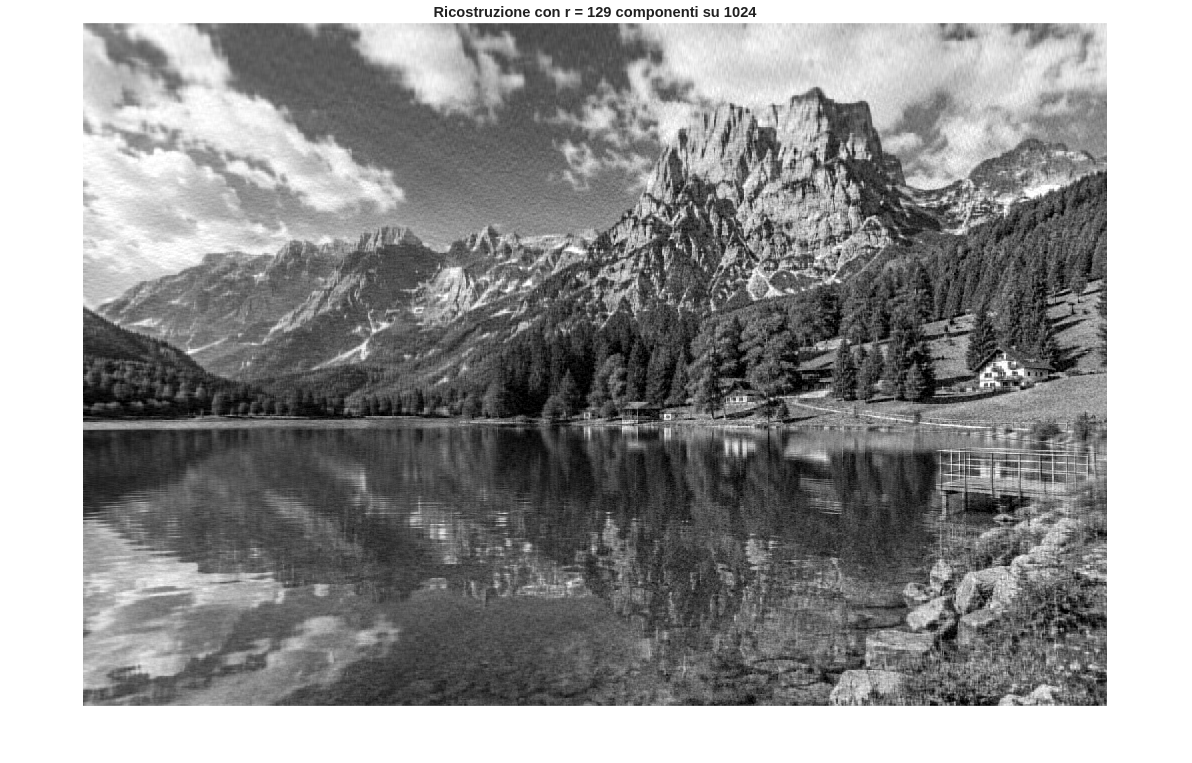

% Ricostruzione Immagine Compressa
I_compressa = U_r*S_r*V_r';

figure;
imshow(uint8(I_compressa));
title(sprintf('Ricostruzione con r = %d componenti su %d', r, length(singvals)));

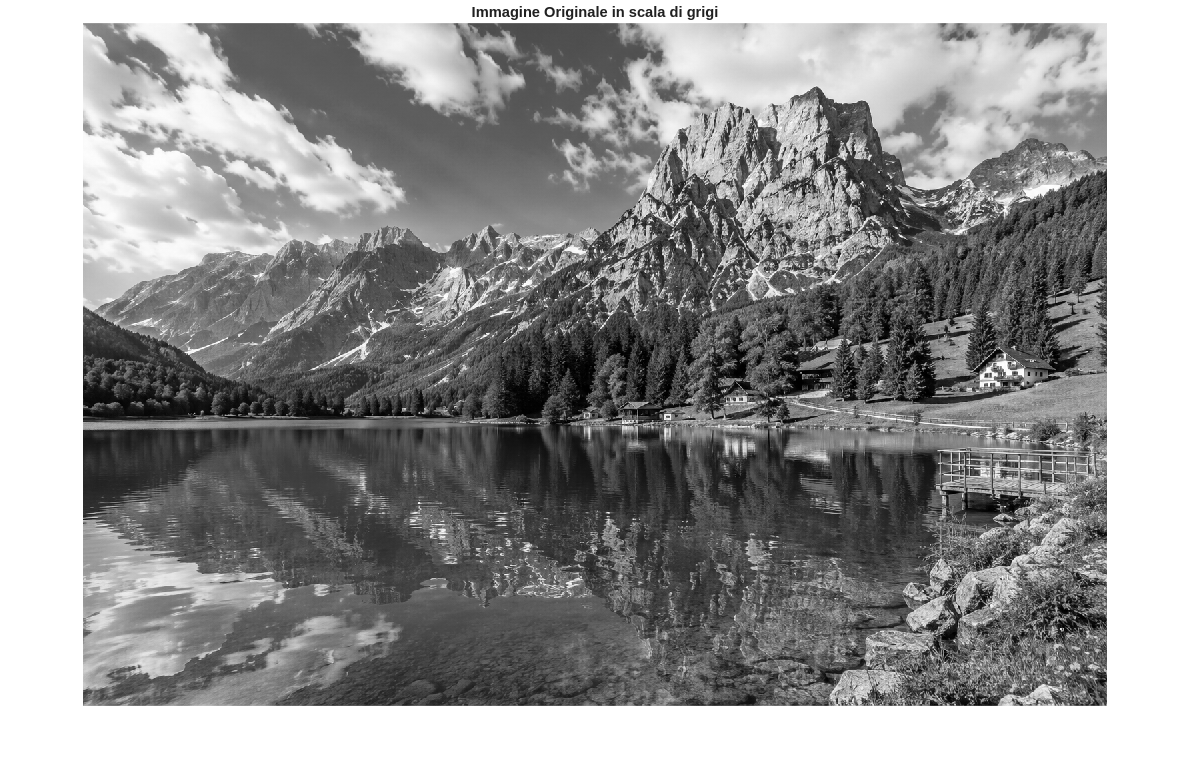

imshow(uint8(I_gray));
title('Immagine Originale in scala di grigi');

### 4.6) Rapposto di Compressione e Errore di Ricostruzione

#### 4.6.1) Rapporto di Compressione 

m_i = size(I,1);
n_i = size(I,2);

num_originale = m_i * n_i *3;
num_compressa = r*(m_i+n_i+1)*3;
tasso_compr = 100*(1-num_compressa/num_originale);
fprintf('Rapporto di Compressione = %.4f%%\n', tasso_compr);

Rapporto di Compressione = 78.9957%


#### 4.6.2) Errore di Ricostruzione 

err = norm(I - I_compressa, 'fro') / norm(I, 'fro');
fprintf('Errore relativo (Frobenius) = %.4f\n', err);

Errore relativo (Frobenius) = 0.1014
